# First Question

process = "stage1 : epsilon = 10 ^(-2)"

epsilon = 0.0100

AwithB =     0.0100    1.0000    1.0100
    1.0000    1.0000    2.0000


CalResult =      1
     1


MainResult =      1
     1


process = "stage2 : epsilon = 10 ^(-4)"

epsilon = 1.0000e-04

AwithB =     0.0001    1.0000    1.0001
    1.0000    1.0000    2.0000


CalResult =      1
     1


MainResult =      1
     1


process = "stage3 : epsilon = 10 ^(-6)"

epsilon = 1.0000e-06

AwithB =     0.0000    1.0000    1.0000
    1.0000    1.0000    2.0000


CalResult =     1.0000
    1.0000


MainResult =      1
     1


process = "stage4 : epsilon = 10 ^(-8)"

epsilon = 1.0000e-08

AwithB =     0.0000    1.0000    1.0000
    1.0000    1.0000    2.0000


CalResult =     1.0000
    1.0000


MainResult =      1
     1


process = "stage5 : epsilon = 10 ^(-10)"

epsilon = 1.0000e-10

AwithB =     0.0000    1.0000    1.0000
    1.0000    1.0000    2.0000


CalResult =     1.0000
    1.0000


MainResult =      1
     1


process = "stage6 : epsilon = 10 ^(-12)"

epsilon = 1.0000e-12

AwithB =     0.0000    1.0000    1.0000
    1.0000    1.0000    2.0000


CalResult =     0.9999
    1.0000


MainResult =      1
     1


process = "stage7 : epsilon = 10 ^(-14)"

epsilon = 1.0000e-14

AwithB =     0.0000    1.0000    1.0000
    1.0000    1.0000    2.0000


CalResult =      1
     1


MainResult =      1
     1


process = "stage8 : epsilon = 10 ^(-16)"

epsilon = 1.0000e-16

AwithB =     0.0000    1.0000    1.0000
    1.0000    1.0000    2.0000


CalResult =          0
    1.0000


MainResult =      1
     1


process = "stage9 : epsilon = 10 ^(-18)"

epsilon = 1.0000e-18

AwithB =     0.0000    1.0000    1.0000
    1.0000    1.0000    2.0000


CalResult =      0
     1


MainResult =      1
     1


process = "stage10 : epsilon = 10 ^(-20)"

epsilon = 1.0000e-20

AwithB =     0.0000    1.0000    1.0000
    1.0000    1.0000    2.0000


CalResult =      0
     1


MainResult =      1
     1


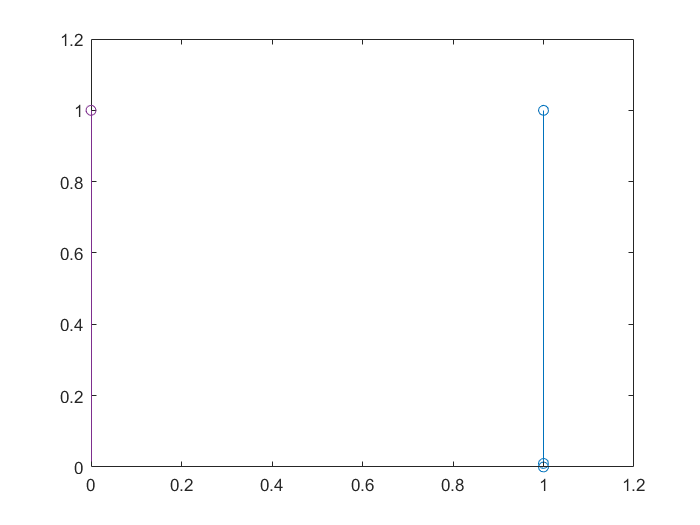

matrixDimension = 2;
for index = 1:10
    process = sprintf("stage%d : epsilon = 10 ^(-%d)",index,2*index)
    epsilon = ((10)^((-2)*index))
    AwithB = [[epsilon,1;1,1],[1 + epsilon;2]]

% Guass Method
AwithB = guass(AwithB,matrixDimension);
% now we have a diagonal matrix

CalResult = zeros(2,1);
    for i = 1:2
    CalResult(i,1) = (AwithB(i,matrixDimension + 1)/AwithB(i,i));   
    end
CalResult   
MainResult = [1;1]
stem(CalResult(1,1),CalResult(2,1))
hold on
end

Question answer : 

as we see in the plot when epsilon decreases, first we feel that the main answer(result) doesn’t have a noticeable change but when

we reach into epsilon = 10 ^ (-16) then suddenly we see that X1 jumps into 2.22 and then in the next step we see that X1 jumps into 

111.02  again in the next step we see that X1 jumps into 11102 so we can conclude that when epsilon decreases too much then 

 X1 increases suddenly but sharply, however X2  doesn’t change too much.

and the main reason of this fact is that when we don’t pivot the matrix then we will have much cancellation error (while

epsilon decreases) and as epsilon decreases  cancellation error during division and multiplication increases much as the fact 

we saw in the plot.

`if we pivot the matrix then we will see that ``the result matrix doesnt change!`

`to see that just change the matrix AwithB = [[epsilon,1;1,1],[1 + epsilon;2] to`

`AwithB = [[1,1;epsilon,1],[2;1+epsilon]] ``then you will see that even at the last step the resutl is: `

`transpose[1,1].`

# Second Question

`function's implementation is at the bottom of the code`

% simple example
A = [2,-1,-2;-4,6,3;-4,-2,8];
determinant(A,3);   % function's implementation is at the bottom of the code

upper =      2    -1    -2
     0     4    -1
     0     0     3


lower =      1     0     0
    -2     1     0
    -2    -1     1


det = 24

# Third Question

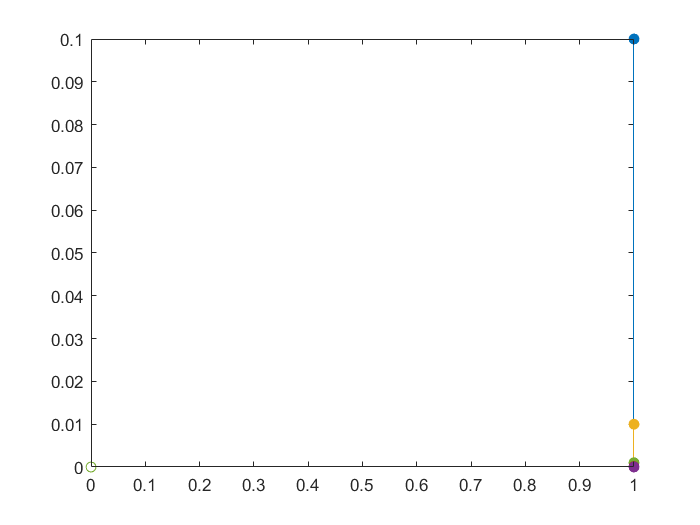

$$mainResult = \left(\begin{array}{c} 1\\ 0.1 \end{array}\right)$$

$$CalResult = \left(\begin{array}{c} 1.0\\ 0.1 \end{array}\right)$$

$$ResultComponentsReleativeError = \left(\begin{array}{c} 0.00000000000000000016927100992577925186725486437816\\ 0.0000000000000000000507089133429592821883259648658 \end{array}\right)$$

$$conditionNumberOfMat = 441.0$$

$$mainResult = \left(\begin{array}{c} 1\\ 0.01 \end{array}\right)$$

$$CalResult = \left(\begin{array}{c} 1.0\\ 0.01 \end{array}\right)$$

$$ResultComponentsReleativeError = \left(\begin{array}{c} 0.0000000000000000012030492173847009714809165716769\\ 0.00000000000000000011969267897681390355892769965998 \end{array}\right)$$

$$conditionNumberOfMat = 40401.0$$

$$mainResult = \left(\begin{array}{c} 1\\ 0.001 \end{array}\right)$$

$$CalResult = \left(\begin{array}{c} 1.0\\ 0.0010000000000000000000000000000001 \end{array}\right)$$

$$ResultComponentsReleativeError = \left(\begin{array}{c} 0.000000000000000016157784168621895781095244435592\\ 0.00000000000000000051069835430388361574611435626171 \end{array}\right)$$

$$conditionNumberOfMat = 4004001.0$$

$$mainResult = \left(\begin{array}{c} 1\\ 0.0001 \end{array}\right)$$

$$CalResult = \left(\begin{array}{c} 1.0\\ 0.000099999999999999999999999999983317 \end{array}\right)$$

$$ResultComponentsReleativeError = \left(\begin{array}{c} 0.00000000000000018267186263546382241630920365726\\ 0.0000000000000000018266272872187518863425799209287 \end{array}\right)$$

$$conditionNumberOfMat = 400040001.0$$

$$mainResult = \left(\begin{array}{c} 1\\ 0.00001 \end{array}\right)$$

$$CalResult = \left(\begin{array}{c} 0.99999999999999999999999999999765\\ 0.000010000000000000000000000002352991 \end{array}\right)$$

$$ResultComponentsReleativeError = \left(\begin{array}{c} 0.0000000000000021693382611071261077766840001902\\ 0.000000000000000006860015620187492290794120175639 \end{array}\right)$$

$$conditionNumberOfMat = 40000400000.999999999999999999987$$

$$mainResult = \left(\begin{array}{c} 1\\ 0.000001 \end{array}\right)$$

$$CalResult = \left(\begin{array}{c} 0.99999999999999999999999999999885\\ 0.0000010000000000000000000000011538212 \end{array}\right)$$

$$ResultComponentsReleativeError = \left(\begin{array}{c} 0.000000000000001519093366156389553365949036525\\ 0.0000000000000000015190926066102761347087647380858 \end{array}\right)$$

$$conditionNumberOfMat = 4000004000001.0000000000000006673$$

matrixDimension = 2;
figure
% samples which are NOT around of epsilonMahchine
% some examples of epsilon from : 0.01 until 0.00000000000000000001 (10 ^ (-16)) 
for index = 1:6
    process = sprintf("stage%d : epsilon = 10 ^(-%d)",index,index);
    epsilon = vpa((10)^((-1)*index));
    AwithB = [[1,1 + epsilon;1 - epsilon,1],[1 + (1 + epsilon)*epsilon;1]];
    justA = [1,1 + epsilon;1 - epsilon,1];
% Gauss Method
AwithB = guass(AwithB,matrixDimension);      
% now we have a diagonal matrix
CalResult = vpa(zeros(2,1));
ResultComponentsReleativeError = vpa(zeros(2,1));
mainResult = [1;epsilon];
    for i = 1:2
    CalResult(i,1) = vpa(AwithB(i,matrixDimension + 1)/AwithB(i,i));  
    ResultComponentsReleativeError(i,1) =vpa(sqrt(abs((CalResult(i,1))^2 - (mainResult(i,1))^2 )));
    end
mainResult
CalResult
ResultComponentsReleativeError
conditionNumberOfMat = conNum(justA)
stem(CalResult(1,1),CalResult(2,1),'filled');
hold on
stem(ResultComponentsReleativeError(1,1),ResultComponentsReleativeError(2,1));
hold on
end

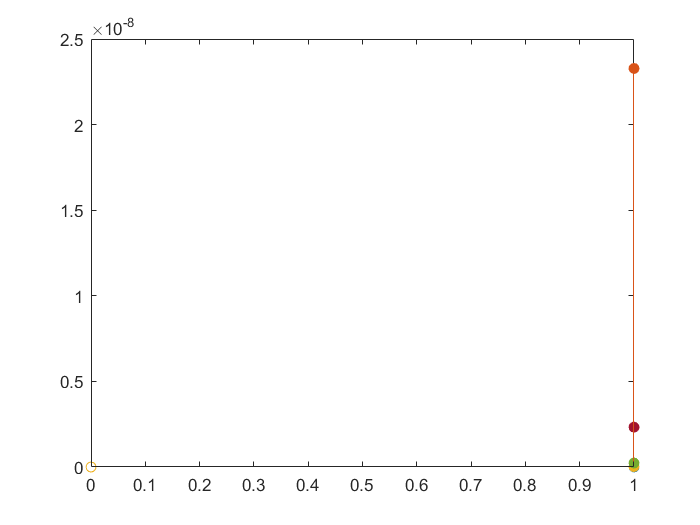

process = "stage -2 : epsilon = sqrt(MachineEpsilon) * 10 ^(-2)"

$$mainResult = \left(\begin{array}{c} 1\\ 0.0000000000023280893453645631030197831589862 \end{array}\right)$$

$$CalResult = \left(\begin{array}{c} 1.0000000000000000086863040478642\\ 0.0000000000023280806590605152590761149126395 \end{array}\right)$$

$$ResultComponentsReleativeError = \left(\begin{array}{c} 0.0000000041680460764881585454329737281241\\ 0.0000000000000063596311494368218020129729042251 \end{array}\right)$$

$$conditionNumberOfMat = 738007380075518898919471.2448026$$

process = "stage -1 : epsilon = sqrt(MachineEpsilon) * 10 ^(-1)"

$$mainResult = \left(\begin{array}{c} 1\\ 0.000000000023280893453645631030197831589862 \end{array}\right)$$

$$CalResult = \left(\begin{array}{c} 1.0000000000000000001106898645745\\ 0.000000000023280893342955766458259638976845 \end{array}\right)$$

$$ResultComponentsReleativeError = \left(\begin{array}{c} 0.00000000047051007337678786739103962585905\\ 0.0000000000000022702241904145212714248154957317 \end{array}\right)$$

$$conditionNumberOfMat = 7380073800909822127308.9859531279$$

process = "stage 0 : epsilon = sqrt(MachineEpsilon) * 10 ^(0)"

$$mainResult = \left(\begin{array}{c} 1\\ 0.00000000023280893453645631030197831589862 \end{array}\right)$$

$$CalResult = \left(\begin{array}{c} 0.99999999999999999999877291728109\\ 0.00000000023280893453768339302060041051833 \end{array}\right)$$

$$ResultComponentsReleativeError = \left(\begin{array}{c} 0.000000000049539534089609087481880609736707\\ 0.00000000000000075587805936045124887414088993955 \end{array}\right)$$

$$conditionNumberOfMat = 73800738024561545304.218882612091$$

process = "stage 1 : epsilon = sqrt(MachineEpsilon) * 10 ^(1)"

$$mainResult = \left(\begin{array}{c} 1\\ 0.0000000023280893453645631030197831589862 \end{array}\right)$$

$$CalResult = \left(\begin{array}{c} 0.99999999999999999999999649739281\\ 0.0000000023280893453645666056269661646931 \end{array}\right)$$

$$ResultComponentsReleativeError = \left(\begin{array}{c} 0.0000000000026467365532519813700721985474988\\ 0.00000000000000012770577484008292702151757481746 \end{array}\right)$$

$$conditionNumberOfMat = 738007381791947860.54739679790979$$

process = "stage 2 : epsilon = sqrt(MachineEpsilon) * 10 ^(2)"

$$mainResult = \left(\begin{array}{c} 1\\ 0.000000023280893453645631030197831589862 \end{array}\right)$$

$$CalResult = \left(\begin{array}{c} 0.99999999999999999999999987819423\\ 0.000000023280893453645631152003594218537 \end{array}\right)$$

$$ResultComponentsReleativeError = \left(\begin{array}{c} 0.00000000000049357018845230455530908974463355\\ 0.000000000000000075309321890430366594065150313644 \end{array}\right)$$

$$conditionNumberOfMat = 7380073972552720.2469947651579866$$

% now some epsilons around sqrt(Machine Epsilon)!!!
% i find out that My epsilon machine is around 5.42e-20;
% i try the calculation for sqrt(MachEps) , sqrt(MachEps)/100 , sqrt(MachEps)/10 , 10*sqrt(MachEps) , 100*sqrt(MachEps) 
% lets go
figure
epsilonMachine = vpa(5.42e-20);
for index = -2:2
    process = sprintf("stage %d : epsilon = sqrt(MachineEpsilon) * 10 ^(%d)",index,index)
    epsilon = sqrt(epsilonMachine)*(10 ^ index);
    AwithB = [[1,1 + epsilon;1 - epsilon,1],[1 + (1 + epsilon)*epsilon;1]]; 
    justA = AwithB(:,1:2);
% Gauss Method
AwithB = guass(AwithB,matrixDimension);      
% now we have a diagonal matrix
CalResult = vpa(zeros(2,1));
ResultComponentsReleativeError = vpa(zeros(2,1));
mainResult = [1;epsilon];
    for i = 1:2
    CalResult(i,1) = vpa(AwithB(i,matrixDimension + 1)/AwithB(i,i));  
    ResultComponentsReleativeError(i,1) =vpa(sqrt(abs((CalResult(i,1))^2 - (mainResult(i,1))^2 )));
    end
mainResult
CalResult
ResultComponentsReleativeError
conditionNumberOfMat = conNum(justA)
stem(CalResult(1,1),CalResult(2,1),'filled');
hold on
stem(ResultComponentsReleativeError(1,1),ResultComponentsReleativeError(2,1));
hold on
end

`Asked Questions Answers:`

1. How accurately is each component determined?What conclusions can you draw from this experiments? 

**Answer: when the epsilon is too  more than sqrt(machine epsilon) as we detemined in the first part we got that in this time**

**condition Number of the Matrix is quite little and relative error in each component of the solution is less to**

**but as we get nearer to sqrt(machine sqrt) as we did at the last examples of first part and mainly at the second part**

**we got that relative error in each component of the solution becomes more and more and mainly the condition Number**

**of matrix increases sharply too... ****So as we get nearer to sqrt(machine epsilon) Not only condition Number of  matrix **

**increases sharply but the also relative error in each component of the solution increases too.**

**and we can also see this fact on th graphs!**

# Fourth Question

%%%%%%%%%% Fucntions's implementations are at the end of Code ( Functions's part! )
% examples : 
% first part a:
A1 = [0.641,0.242;0.321,0.121];
A2 = [10,-7,0;-3,2,6;5,-1,5];
[CalculatedNorm2_INVA1,CalculatedNormInf_INVA1] = findConditionNumber(A1,2)

U1 =     0.6410    0.2420
         0   -0.0002


$$Cmat = \left(\begin{array}{cccc} 1 & -1 & -1 & 1\\ -1 & 1 & -1 & 1 \end{array}\right)$$

$$Vmat = \left(\begin{array}{cccc} \frac{1000}{641} & -\frac{1000}{641} & -\frac{1000}{641} & \frac{1000}{641}\\ \frac{4011854410438965}{549755813888} & -\frac{4011854410438965}{549755813888} & \frac{7251324619547665}{2199023255552} & -\frac{7251324619547665}{2199023255552}\\ 7297.5208279120876973977764936339 & 7297.5208279120876973977764936339 & 3297.5210301911107082132774011268 & 3297.5210301911107082132774011268 \end{array}\right)$$

$$CalculatedNorm2\_INVA1 = 6332.579415186376820370844774434$$

$$CalculatedNormInf\_INVA1 = 6625.4691463174938929082859897232$$

MATLAB_NORM2_OF_invA1 = vpa(norm(inv(A1),2));
MATLAB_NORM_INF_OF_invA1= vpa(norm(inv(A1),'inf'));
[CalculatedNorm2_INVA2,CalculatedNormInf_INVA2] = findConditionNumber(A2,3);

U1 =    10.0000   -7.0000         0
         0    2.5000    5.0000
         0         0    6.2000


$$Cmat = \left(\begin{array}{cccccccc} 1 & 1 & 1 & -1 & -1 & -1 & -1 & 1\\ 1 & -1 & -1 & 1 & 1 & -1 & -1 & 1\\ -1 & 1 & -1 & 1 & -1 & 1 & -1 & 1 \end{array}\right)$$

$$Vmat = \left(\begin{array}{cccccccc} \frac{1}{10} & \frac{1}{10} & \frac{1}{10} & -\frac{1}{10} & -\frac{1}{10} & -\frac{1}{10} & -\frac{1}{10} & \frac{1}{10}\\ \frac{17}{25} & -\frac{3}{25} & -\frac{3}{25} & \frac{3}{25} & \frac{3}{25} & -\frac{17}{25} & -\frac{17}{25} & \frac{17}{25}\\ -\frac{22}{31} & \frac{8}{31} & -\frac{2}{31} & \frac{2}{31} & -\frac{8}{31} & \frac{22}{31} & \frac{12}{31} & -\frac{12}{31}\\ 0.98794839923051831443025315193761 & 0.30165757819904268148145815484156 & 0.16900393754379503185346904820751 & 0.16900393754379503185346904820751 & 0.30165757819904268148145815484156 & 0.98794839923051831443025315193761 & 0.78882438640742527981861519920769 & 0.78882438640742527981861519920769 \end{array}\right)$$

MATLAB_NORM2_OF_invA2 = vpa(norm(inv(A2),2));
MATLAB_NORM_INF_OF_invA2 = vpa(norm(inv(A2),'inf'));
% second part b
% choose random V vectors!
yVecsA2 = zeros(3,5); 
yVecsA2(:,1) = [2;4;0];
yVecsA2(:,2) = [0.5;0.8;0];
yVecsA2(:,3) = [1.6;0.3;0];
yVecsA2(:,4) = [0.34;1.4;0];
yVecsA2(:,5) = [0.2;0.4;0];
yVecsA1 = zeros(2,5); 
yVecsA1(:,1) = [2;4];
yVecsA1(:,2) = [0.5;0.8];
yVecsA1(:,3) = [1.6;0.3];
yVecsA1(:,4) = [0.34;1.4];
yVecsA1(:,5) = [0.2;0.4];
ZA1vectors = zeros(2,5)

ZA1vectors =      0     0     0     0     0
     0     0     0     0     0


ZA2vectors = zeros(3,5)

ZA2vectors =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


for j = 1:5
    ZA1vectors(:,j) = mldivide(A1,yVecsA1(:,j))
    ZA2vectors(:,j) = mldivide(A2,yVecsA2(:,j))
end

ZA1vectors = 	1.0e+04 *

    0.6000         0         0         0         0
   -1.5884         0         0         0         0


ZA2vectors =    -1.1097         0         0         0         0
   -1.8710         0         0         0         0
    0.7355         0         0         0         0


ZA1vectors = 	1.0e+04 *

    0.6000    0.1100         0         0         0
   -1.5884   -0.2912         0         0         0


ZA2vectors =    -1.1097   -0.2323         0         0         0
   -1.8710   -0.4032         0         0         0
    0.7355    0.1516         0         0         0


ZA1vectors = 	1.0e+04 *

    0.6000    0.1100   -0.1000         0         0
   -1.5884   -0.2912    0.2655         0         0


ZA2vectors =    -1.1097   -0.2323   -0.2329         0         0
   -1.8710   -0.4032   -0.5613         0         0
    0.7355    0.1516    0.1206         0         0


ZA1vectors = 	1.0e+04 *

    0.6000    0.1100   -0.1000    0.2460         0
   -1.5884   -0.2912    0.2655   -0.6515         0


ZA2vectors =    -1.1097   -0.2323   -0.2329   -0.3512         0
   -1.8710   -0.4032   -0.5613   -0.5503         0
    0.7355    0.1516    0.1206    0.2412         0


ZA1vectors = 	1.0e+04 *

    0.6000    0.1100   -0.1000    0.2460    0.0600
   -1.5884   -0.2912    0.2655   -0.6515   -0.1588


ZA2vectors =    -1.1097   -0.2323   -0.2329   -0.3512   -0.1110
   -1.8710   -0.4032   -0.5613   -0.5503   -0.1871
    0.7355    0.1516    0.1206    0.2412    0.0735


CondNumsA1_2 = zeros(1,5);
CondNumsA1Inf = zeros(1,5);
CondNumsA2_2 = zeros(1,5);
CondNumsA2Inf = zeros(1,5);
for i = 1:5
    CondNumsA1_2(1,i) = vpa(norm(ZA1vectors(:,i),2)/norm(yVecsA1(:,i),2));
    CondNumsA1Inf(1,i) = vpa(norm(ZA1vectors(:,i),'inf')/norm(yVecsA1(:,i),'inf'));
    CondNumsA2_2(1,i) = vpa(norm(ZA2vectors(:,i),2)/norm(yVecsA2(:,i),2));
    CondNumsA2Inf(1,i) = vpa(norm(ZA2vectors(:,i),'inf')/norm(yVecsA2(:,i),'inf'));
end
MATLAB_NORM2_OF_invA2

$$MATLAB\_NORM2\_OF\_invA2 = 0.69277601494716223307079872029135$$

MATLAB_NORM_INF_OF_invA2

$$MATLAB\_NORM\_INF\_OF\_invA2 = 1.0$$

MATLAB_NORM2_OF_invA1

$$MATLAB\_NORM2\_OF\_invA1 = 6332.5794426604306863737292587757$$

MATLAB_NORM_INF_OF_invA1

$$MATLAB\_NORM\_INF\_OF\_invA1 = 7950.4132231406711071031168103218$$

Cond2NumA2 = vpa(max(CondNumsA1_2))

$$Cond2NumA2 = 4833.4619320996180249494500458241$$

CondinfNumA2 = vpa(max(CondNumsA2Inf))

$$CondinfNumA2 = 0.50403225806451612903225806451613$$

CondinfNumA1 = vpa(max(CondNumsA1Inf))

$$CondinfNumA1 = 4653.2467532468563149450346827507$$

Cond2NumA1 = vpa(max(CondNumsA2_2))

$$Cond2NumA1 = 0.51877267861177246927470356590231$$

`as we see the first method's precision is more than second method's precision which we`

`used random matrixs in and the first method's calculation is more accurate than second one!`

# `Functions's part`

function det = determinant(mat,dimension)  %%% LU factorizaiotn:second Question determinant calculater function
lower = zeros(dimension,dimension);
upper = zeros(dimension,dimension);
for i = 1:dimension
    lower(i,i) = 1;
end

for i = 1:dimension 
        % Upper Triangular 
        for k = i:dimension 
  
            % Summation of L(i,j) * U(j,k) 
         sum = 0; 
            for j = 1:i-1
                sum = sum + (lower(i,j) * upper(j,k));
            end
            % Evaluating U(i,k) 
            upper(i,k) = mat(i,k) - sum;
        end
        % Lower Triangular 
        for k = i:dimension
            if (i == k) 
                lower(i,i) = 1; % Diagonal as 1     
                else  
                % Summation of L(k, j) * U(j, i) 
                sum = 0; 
                    for j = 1:i-1 
                    sum = sum + (lower(k,j) * upper(j,i)); 
                    end
                % Evaluating L(k, i) 
                lower(k,i) = (mat(k,i) - sum) / upper(i,i); 
            end
        end
end

upper  % display lower matrix
lower  % diplay  upper matrix
detupper = 1; % lower matrix's determinant 
detlower = 1; % upper matrix's determinant
for i = 1:dimension
    detlower = detlower*lower(i,i);
    detupper = detupper*upper(i,i);
end
det  = detlower * detupper  % as the fact that if A = B * C we have: det(A) = det(B)*det(C).
end

%%%%%%%%%%%%  ConditionNumber

function conditionNumber = conNum(mat)
infNormofMat = norm(mat,'inf');
infNormofMatInverse = norm(inv(mat),'inf');
conditionNumber = infNormofMat * infNormofMatInverse;
end

%%%%%%%%%%%%  Guass Method

function guassMat = guass(AwithB,matrixDimension)

for k=1:matrixDimension-1  % this fat FOR makes all the elements of the A matrix which are under the main diameter ZERO
        for i=k+1:matrixDimension
            m=AwithB(i,k)/AwithB(k,k);
            for j=k:matrixDimension+1
            AwithB(i,j)=AwithB(i,j)-m*AwithB(k,j);
            end
        end
end

   for k=1:matrixDimension-1   % this fat FOR makes all the elements of the A matrix which are upper the main diameter ZERO
        for i=1:k
            m=vpa(AwithB(i,k+1)/AwithB(k+1,k+1));
            for j=k+1:matrixDimension+1
            AwithB(i,j)=AwithB(i,j)-m*AwithB(i+1,j);
            end
        end
   end
guassMat = AwithB;   
end

%%%%%%%%%%    solving the equation: Transpose(U) * Y = C; 

function AnswerVector = findTriangleAnswer(UTranspose,C,dimension)

AnswerVector = zeros(dimension,1);
sum =  0;
for i = 1:dimension 
    for j = 1:(i-1)
        sum = sum + UTranspose(i,j) * AnswerVector(j,1);
    end
AnswerVector(i,1) = vpa(C(i,1)-sum)/UTranspose(i,i); 
sum = 0;
end

end





%%%%%%%%    findConditionNumber    
function [NORM2,NORMINF] = findConditionNumber(A1,A1dimension)

[~,U1] = lu(A1)
coloumnIndexNum = 2 ^ A1dimension;
% create all C vectors
Cmat = vpa(zeros(A1dimension,coloumnIndexNum)); % the last line is for vector's condition number
Vmat = vpa(zeros(A1dimension + 1,coloumnIndexNum));
for i = 1:A1dimension
    for j = 1:coloumnIndexNum
        Cmat(i,j) = 1;
    end
end
for i = 1:A1dimension
    for j = 1:(coloumnIndexNum)
        Cmat(i,j) = Cmat(i,j) * ((-1)^(floor(j/(coloumnIndexNum/(2^(i))))));
    end
end
Cmat

for i = 1:coloumnIndexNum
Vmat(1:A1dimension,i) = findTriangleAnswer(transpose(U1),Cmat(:,i),A1dimension); 
end
% now lets find the vector which is more in magnitude
for i = 1:coloumnIndexNum
TempSum = 0;     
    for j = 1:A1dimension
    TempSum = TempSum + Vmat(j,i)^2; 
    end
    Vmat(A1dimension + 1,i) = vpa(sqrt(TempSum));  
end
Vmat
maxMagnitude = max(Vmat(A1dimension + 1,:));
for i = 1:coloumnIndexNum
    if( Vmat(A1dimension + 1,i) == maxMagnitude )
      % mainV = Vmat(1:2,i);
        mainC = Cmat(1:A1dimension,i);
        break
    end
end
Ymat = vpa(mldivide(transpose(A1),mainC));
foundZ = mldivide(A1,Ymat);
NORM2 = norm(foundZ,2)/norm(Ymat,2);
NORMINF = norm(foundZ,'inf')/norm(Ymat,'inf');
end
